# ベクトルおよび部分空間の直行性

## ベクトルの長さ

n次元ベクトル$x=\left\lbrack \begin{array}{c}
x_1  & \cdots  & x_n 
\end{array}\right\rbrack$の長さ$\left\|x\right\|$は


$${\left\|x\right\|}^2 =x_1^2 +x_2^2 +\cdots +x_n^2$$


の正の平方根

## ベクトルの内積


$$x^T y=\left\lbrack \begin{array}{c}
x_1  & \cdots  & x_n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_1 \\
\vdots \\
y_n 
\end{array}\right\rbrack =x_1 y_1 +\cdots +x_n y_n$$


**ベクトルが直交するとき内積は0**

## 2.5.1

clear
x = [1,4,0,2]'

x =        1       
       4       
       0       
       2       


y = [2,-2,1,3]'

y =        2       
      -2       
       1       
       3       


x_lng = 1^2 + 4^2 + 2^2

x_lng =       21       


y_lng = 2^2 + 2^2 + 1^2 + 3^2

y_lng =       18       


dot(x,y) % x'*y

ans =        0       


## 2.5.2

$\left\lbrack \begin{array}{c}
1 & 0
\end{array}\right\rbrack と\left\lbrack \begin{array}{c}
1 & 1
\end{array}\right\rbrack$は独立だが、直交していない

$\left\lbrack \begin{array}{c}
0 & 0
\end{array}\right\rbrack と\left\lbrack \begin{array}{c}
1 & 1
\end{array}\right\rbrack$は直交しているが独立でない

## 2.5.3


$$\begin{array}{l}
\frac{x_2 }{x_1 }\times \frac{y_2 }{y_1 }=-1\\
\frac{x_2 y_2 }{x_1 y_1 }=-1\\
x_2 y_2 =-x_1 y_1 \\
x_1 y_1 +x_2 y_2 =0
\end{array}$$


ここで、


$$x^T y=$$

$$x_1 y_1 +x_2 y_2$$


なので、

直交性の条件と等しい

## 2.5.4


$$B∗B^{-1} =I$$


なので$i\ne j$ならば$I_{\mathrm{ij}}$は0でなくてはならない

よって直交している

## 2.5.5

clear
v1 = [1,2,-2,1]'

v1 =        1       
       2       
      -2       
       1       


v2 = [4,0,4,0]'

v2 =        4       
       0       
       4       
       0       


v3 = [1,-1,-1,-1]'

v3 =        1       
      -1       
      -1       
      -1       


dot(v1,v2)

ans =       -4       


dot(v1,v3)

ans =        0       


dot(v2,v3)

ans =        0       


## 2.5.6

clear
x = [1,1,1]'

x =        1       
       1       
       1       


y = [1,-1,0]'

y =        1       
      -1       
       0       


syms u v w
b = [u;v;w]

$$b = \left(\begin{array}{c} u\\ v\\ w \end{array}\right)$$

eqn1 = dot(x,b) == 0

$$eqn1 = u+v+w=0$$

eqn2 = dot(y,b) == 0

$$eqn2 = u-v=0$$


$$\begin{array}{l}
u=v\\
2v+w=0\\
w=-2v
\end{array}$$



$$\left\lbrack \begin{array}{c}
1\\
1\\
-2
\end{array}\right\rbrack v$$


よって${\left\lbrack \begin{array}{c}
1\\
1\\
-2
\end{array}\right\rbrack }^T$の乗数倍が直交

また単位ベクトルは


$$\begin{array}{l}
\left\lbrack \begin{array}{c}
\frac{1}{\sqrt{3}} & \frac{1}{\sqrt{3}} & \frac{1}{\sqrt{3}}
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
\frac{1}{\sqrt{2}} & -\frac{1}{\sqrt{2}} & 0
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{c}
\frac{1}{\sqrt{6}} & \frac{1}{\sqrt{6}} & -\frac{2}{\sqrt{6}}
\end{array}\right\rbrack 
\end{array}$$


## 直交部分空間

部分空間$V$と$W$が直交する条件は「$V$のすべてのベクトル$v_n$が$W$のすべてのベクトル$w_n$と直交している」

**例**


$$\begin{array}{l}
v_1 =\left\lbrack \begin{array}{c}
1 & 0 & 0 & 0
\end{array}\right\rbrack ,v_2 =\left\lbrack \begin{array}{c}
1 & 1 & 0 & 0
\end{array}\right\rbrack \\
w_1 =\left\lbrack \begin{array}{c}
0 & 0 & 4 & 5
\end{array}\right\rbrack 
\end{array}$$


で張られる空間VとWは、$w_1$が$v_1 ,v_2$と直交するので直線Wは平面Vに直交している

## 2.5.7

clear
v1 = [1,0,0,0]

v1 =        1              0              0              0       


v2 = [1,1,0,0]

v2 =        1              1              0              0       


w1 = [0,0,4,5]

w1 =        0              0              4              5       


syms a
w2 = [0,0,0,a]

$$w2 = \left(\begin{array}{cccc} 0 & 0 & 0 & a \end{array}\right)$$

dot(v1,w2)

$$ans = 0$$

dot(v2,w2)

$$ans = 0$$

syms a b c d
v3 = [0,0,5,-4]

v3 =        0              0              5             -4       


dot(w1,v3)

ans =        0       


## 2.5.8

$V$と$W$が直交するということは、それぞれに含まれるベクトル同士の内積がすべて0でなければならない

もし、0ベクトル以外の共通ベクトルがあると、自身で内積をとることになるが、内積は0ベクトルでない限り0にならない

よって、$V\cap W=\left\lbrace 0\right\rbrace$となる

## 基本部分空間の直交について

任意の$m\times n$行列$A$について、零空間と行空間は${\mathbf{R}}^n$の直行する部分空間である

同様に、左零空間と列空間は${\mathbf{R}}^m$の直交部分空間である

## 例


$$A=\left\lbrack \begin{array}{c}
0 & 1 & 4 & 0\\
0 & 2 & 8 & 0
\end{array}\right\rbrack \longrightarrow U=\left\lbrack \begin{array}{c}
0 & 1 & 4 & 0\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$


基底変数は第2列、他が自由変数

この時、順に各自由変数を1とおき、$\mathit{Ux}=0$を解くと$A$の零空間の基底を得られる


$$\left\lbrack \begin{array}{c}
1\\
0\\
0\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
-4\\
1\\
0
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
0\\
0\\
0\\
1
\end{array}\right\rbrack$$


上記定理より、これらはすべてAの行と直交している

また、Aの列空間は1次元であり、基底変数の列$\left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack$だけで張られる

左零空間は、$y^T A=0$より$\left\lbrack \begin{array}{c}
-2 & 1
\end{array}\right\rbrack$となる

そして、これらは


$$\left\lbrack \begin{array}{c}
-2 & 1
\end{array}\right\rbrack \cdot \left\lbrack \begin{array}{c}
1\\
2
\end{array}\right\rbrack =0$$


となり、直交している

また、**零空間は行空間に直交するすべてのベクトルを含む**

そのような空間を「**直交補空間**」とよぶ

## 線形代数の基本定理（その2）

- 零空間は行空間の直交補空間であり、行空間は零空間の直交補空間

- 左零空間は列空間の直交補空間であり、列空間は左零空間の直交補空間

$\mathit{Ax}=b$が解をもつのは$b$が左零空間に直交しているときに限る

$b$が列空間にあるのは、$A^T y=0$のすべての解$y$に$b$が直交しているときに限る

**部分空間が直交補空間になる条件**

$V$と$W$が${\mathbf{R}}^n$の部分空間の場合、以下の条件のうち1つを満たせば直交補空間となる

- 
$$W=V^{\perp }$$


- 
$$V=W^{\perp }$$


- $V$と$W$は直交しており、かつ$\mathrm{dimV}+\mathrm{dimW}=n$

## この節と前節の概要

ある行列$A\left(m\times n\right)$において

①4つの基本部分空間の**次元**が決定された

    ・行空間と列空間の次元は同じ（$r$）

②4つの基本部分空間の**方向**が決定された

    ・左零空間と列空間は${\mathbf{R}}^m$においてたがいに直交補空間

    ・零空間と行空間は${\mathbf{R}}^n$においてたがいに直交補空間

任意の$x$は$x_r {\mathrm{とx}}_n$に分解され、この時、行列Aが持つ作用は

$A$の行空間の成分$x_r$を列空間のベクトル${\mathit{Ax}}_r =\mathit{Ax}$に移す

零空間の成分$x_n$を0(${\mathit{Ax}}_n =0$)に移す

行空間から列空間への写像は正則⇒逆可能⇒列空間の全てのベクトル$b$がそれぞれ行空間のただ1つのベクトル$x$から移される

## 2.5.9

clear

A =        1              1              2       
       1              2              3       


A = [1,1,2;1,2,3]
E21 = eye(2);

E21 =        1              0       
      -1              1       


E21(2,1) = -1

U =        1              1              2       
       0              1              1       


U = E21 * A
syms u v w

$$ans = \left(\begin{array}{c} u+v+2\,w\\ v+w \end{array}\right)$$

U * [u;v;w]


$$u=-v-2w$$



$$v=-w$$



$$u=-w$$



$$-w\left\lbrack \begin{array}{c}
1\\
1\\
-1
\end{array}\right\rbrack$$


よって、$\left\lbrack \begin{array}{c}
1\\
1\\
-1
\end{array}\right\rbrack$で張られる空間（直線）

## 2.5.10

解がベクトル(1,2,2)と(1,2,3)の線形結合であるような⇒零空間に解がある

つまり、これらとの内積が0になるようなベクトルを求めればよい

clear

A =        1              1              2       
       1              2              3       


A = [1,1,2;1,2,3]
E21 = eye(2);

E21 =        1              0       
      -1              1       


E21(2,1) = -1

U =        1              1              2       
       0              1              1       


U = E21 * A
syms u v w

$$ans = \left(\begin{array}{c} u+v+2\,w\\ v+w \end{array}\right)$$

U * [u;v;w]


$$u=-v-2w$$



$$v=-w$$



$$u=-w$$



$$-w\left\lbrack \begin{array}{c}
1\\
1\\
-1
\end{array}\right\rbrack$$


よって、$\left\lbrack \begin{array}{c}
1\\
1\\
-1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x & y & z
\end{array}\right\rbrack =0$

## 2.5.11

$b$を列空間と左零空間の成分に分解


$$b=b_r +b_{\mathrm{lz}}$$


この時


$$b_r =\mathit{Ax}$$



$$b_{\mathrm{lz}} =A^T y$$


なので、


$$b=b_r +b_{\mathrm{lz}} =\mathit{Ax}+A^T y=\mathit{Ax}$$


## 2.5.12

clear

A =        1              0              2       
       1              1              4       


A = [1,0,2;1,1,4]

P12 =        0              1       
       1              0       


P12 = [0,1;1,0]

PA =        1              1              4       
       1              0              2       


PA = P12 * A
E21 = eye(2);

E21 =        1              0       
      -1              1       


E21(2,1) = -1

U =        1              0              2       
       0              1              2       


U = E21 * A
syms u v w
U * [u;v;w]



$$\begin{array}{l}
u=-2w\\
v=-2w
\end{array}$$



$$\left\lbrack \begin{array}{c}
-2w\\
-2w\\
w
\end{array}\right\rbrack =-w\left\lbrack \begin{array}{c}
2\\
2\\
-1
\end{array}\right\rbrack$$


x = [2;2;-1]

dot(A(1,:),x)

$$ans = \left(\begin{array}{c} u+2\,w\\ v+2\,w \end{array}\right)$$

x =        2       
       2       
      -1       


ans =        0       


ans =        0       


dot(A(2,:),x)

## 2.5.13


$$\begin{array}{l}
\left(V+W\right)x=0\\
\mathit{Vx}+\mathit{Wx}=0
\end{array}$$


この時、VとWは空間⇒$\mathit{Vx}\ne -\mathit{Wx}$なので、


$$\mathit{Vx}=\mathit{Wx}=0$$


## この辺りは実際の信号処理にどう役立つか

解に自由変数が多い⇒制限が少なすぎて、解が定まらない⇒実験がうまく収束しない

解がない⇒いくらやったところで理論的な解が得られない⇒実験でできても理由がわからないから製品に使えない

ここの章を理解していると、シミュレーション（モデル）の段階でそれがわかる

## **生起行列とKirchhoffの法則**

- 全ての端点で入ってくる電流の和は出ていく電流の輪に等しい$\sum_{i=1}^N I_i =0$

- 全ての閉回路を一巡すれば、電圧降下の和は0である$\sum_{i=1}^N V_i =0$

これらは**グラフ理論**に関係している

（端点がどのように結ばれているかとその方向に依存し、回路の抵抗には依存しない）

端点間の結合は**グラフの生起行列**によって記述できる

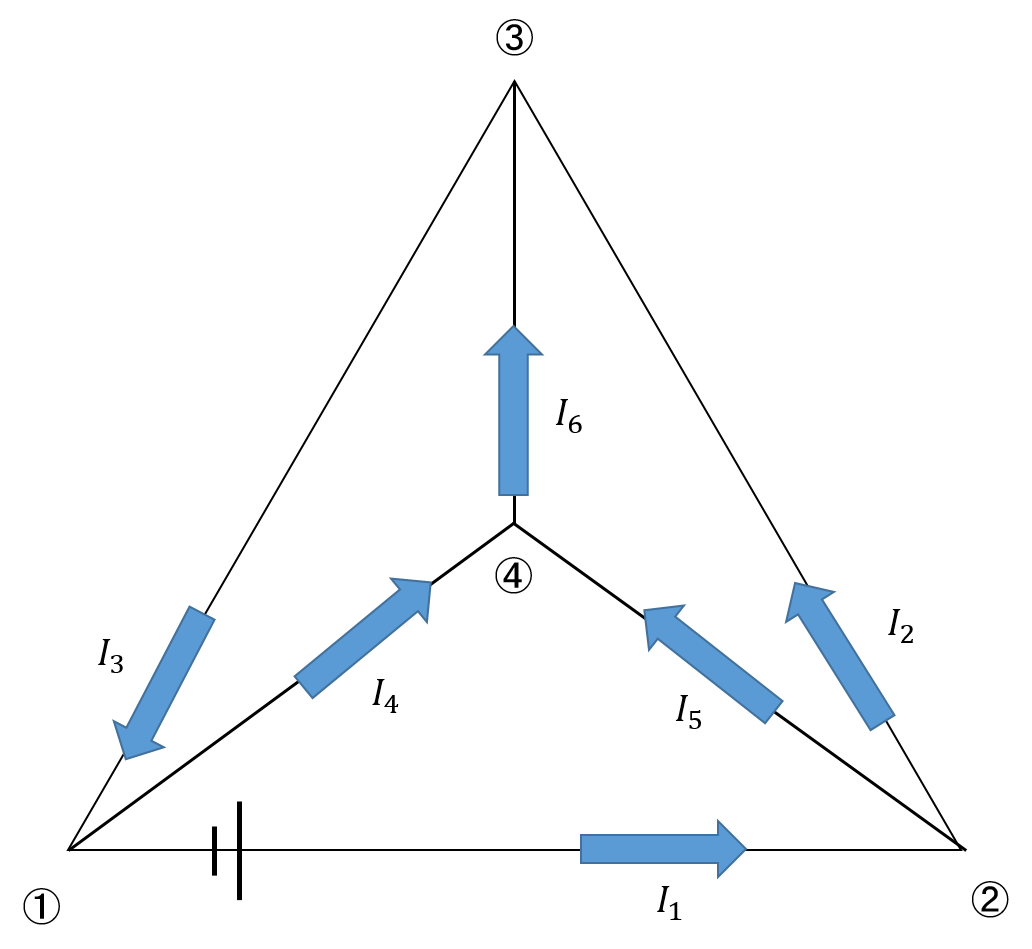

この図の生起行列は


$$M=\left\lbrack \begin{array}{c}
1 & 0 & -1 & 1 & 0 & 0\\
-1 & 1 & 0 & 0 & 1 & 0\\
0 & -1 & 1 & 0 & 0 & -1\\
0 & 0 & 0 & -1 & -1 & 1
\end{array}\right\rbrack$$


となり、行が端点1~4に、列が枝1~6に対応、+1と-1は枝の始点と終点を表す

また、6つの電流によって構成される列ベクトルを$I$とすると、キルヒホッフの第一法則により


$$\mathit{MI}=0$$


となる⇒6つの未知数を持つ4つの方程式

電圧降下に関しては、端点の電圧を$p_i$、電圧降下を$E$とすると電位ベクトル$p$を用いて


$$M^T p=E$$


となる

このことから、$I$**は**$M$**の零空間にあり、**$E$**は**$M$**の行空間にある**

また、零空間と行空間は直交しているので、


$$E^T I=0$$


## 2.5.15

例より


$$\begin{array}{l}
p_2 -p_3 =p_3 -p_1 =5\\
p_3 =p_4 
\end{array}$$


となり、


$$p_1 =0$$


より


$$\begin{array}{l}
p_1 =0\\
p_2 =10\\
p_3 =5\\
p_4 =5
\end{array}$$


clear
M = [1,0,-1,1,0,0;-1,1,0,0,1,0;0,-1,1,0,0,-1;0,0,0,-1,-1,1]

M =        1              0             -1              1              0              0       
      -1              1              0              0              1              0       
       0             -1              1              0              0             -1       
       0              0              0             -1             -1              1       


p = [0;10;5;5]

p =        0       
      10       
       5       
       5       


E = M' * p

E =      -10       
       5       
       5       
      -5       
       5       
       0       



I = [2;1;1;-1;1;0]

I =        2       
       1       
       1       
      -1       
       1       
       0       


E' * I

ans =        0       


## 2.5.16